%% WHOLE CODE
clear

%----------------------------------------------------------------
% @SET: fish + conditions
%----------------------------------------------------------------
nfish = 1;
cond_codes = [300:303];
message = 'tren largo - no aleat (intra?)';

%----------------------------------------------------------------
% @SET: MEASURE (OR LOOP THROUGH ALL MEASURES)
%----------------------------------------------------------------
% measure = {'slopemean'};
% measure = {'slopemax'};
% measure ={'onsetnoise_ms'};
% measure = {'peakminusbasel'};
measure = {'peakminusbasel' 'slopemean' 'slopemax' 'onsetnoise_ms'};

%----------------------------------------------------------------
% @SET: MEASURE (OR LOOP THROUGH ALL MEASURES)
%----------------------------------------------------------------
reject_on= 0;

setting.manual_reject = 0; %
setting.GSmethod_reject = 1;  %
setting.GSabsthres_reject = 1; %
setting.force_include = 0; %

roiname1 = 'dm4m_R';
roiname2 = 'dm2_R';

wavesylim.ave = [-0.2 0.4]; %ylim for pltting average waves
wavesylim.all = [-0.2 0.6]; %ylim for plotting all waves (has to be higher)

% user_settings
path.rootpath = '/home/tamara/Documents/MATLAB/VSDI/VSDI_ourToolbox/';
path.TORus = '/home/tamara/Documents/MATLAB/VSDI/TORus';
path.data = fullfile(path.TORus, 'data');
path.grouplist = path.TORus;
path.list =fullfile(path.TORus, 'data','BVlists');
addpath(genpath(path.rootpath));
addpath(path.TORus);
% end of user_settings

[VSDI] = TORus('load',nfish);

TORus_210320_loaded



tempmov = TORus('loadmovie',nfish,'_09filt3');

TORusMov_210320_09filt3.mat_loaded


movies = tempmov.data(:,:,1:end-1,:);

display([num2str(VSDI.ref) '-block:' num2str(cond_codes(1)) message]) % DISPLAY FISH AND BLOCK INFO

210320-block:300tren largo - no aleat (intra?)



VSDroiTS = TORus('loadwave',nfish);

ROIs timeseries for fishTORus_210320_loaded


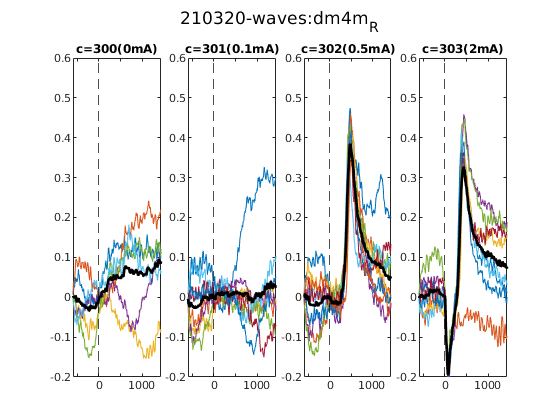

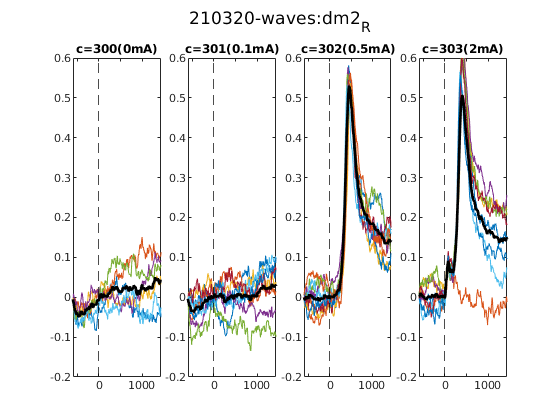

fcode =  'filt309';
field = ['circ_' fcode] ;
waves = VSDroiTS.(field).data; %@ SET: whether circ_filt06, circ_filt09, or filt06

%----------------------------------------------------------------
% @SET: PEAK2PEAK CONFIGURATION
%----------------------------------------------------------------

method = 'movsum';
lat_limit = 1000; %for trial rejection

% Window For trial-wise analysis
window.min = [-100 100];
window.max = [0 600];
window.movsum = 50;%ms
window.baseline = [-300 0];
window.slope = 50; %ms


noise.fr_abovenoise = 30;
noise.SDfactor = 2;

% Window For average-based analysis

window_ave = window;

noise_ave = noise;
noise_ave.SDfactor = 4;% SET differences



% SELECT EXCLUDED

rejectidx = [];

if setting.manual_reject
    rejectidx = [rejectidx  makeRow(VSDI.reject.manual)];
end

if setting.GSabsthres_reject
    rejectidx = [rejectidx  makeRow(VSDI.reject.GSabs025)];
    
end

if setting.GSmethod_reject
    rejectidx = [rejectidx makeRow(VSDI.reject.GSdeviat2sd)];
end

if setting.force_include
    rejectidx = setdiff(rejectidx, VSDI.reject.forcein);
    
end

rejectidx = sort(unique(rejectidx));

% roiname to roi-idx
nroi1 = name2idx(roiname1, VSDI.roi.labels);
nroi2 = name2idx(roiname2, VSDI.roi.labels);

selroi = [nroi1 nroi2];

%% ----------------------------------------------------------------
%----------------------------------------------------------------
% PLOT WAVES ERPS
%----------------------------------------------------------------
%----------------------------------------------------------------
clearvars -except measure reject_on nfish cond_codes VSDI movies waves fcode ...
    window window_ave noise noise_ave rejectidx roiname1 roiname2 method lat_limit...
    wavesylim selroi setting
nplot = length(cond_codes);
plotcol = 4;
plotrow = ceil(nplot/4);

for nroi = makeRow(selroi)
    
    figure
    for ploti = 1:length(cond_codes)
        localtrials = [];
        localtrials  = find(VSDI.condition(:,1)==cond_codes(ploti));
        
        if reject_on  %@ SET
            localtrials = setdiff(localtrials, rejectidx);
        end
        
        localwaves= squeeze(waves(:,nroi,localtrials));
        
        ax(ploti) = subplot(plotrow,plotcol,ploti);
        plot(VSDI.timebase, localwaves, 'linewidth', 0.4); hold on
        plot (VSDI.timebase, mean(localwaves, 2), 'k', 'linewidth',2)
        ylim(wavesylim.all);
        xline(0, '--k');
        condidx = find(VSDI.condition(:,1) ==cond_codes(ploti)); % get idx from condition
        tempmA = VSDI.condition(condidx(1),4); %get mA from first trial that meet the condition
        title(['c=',num2str(cond_codes(ploti)), '(', num2str(tempmA),'mA)']);
        
        localtitle = strcat(num2str(VSDI.ref), '-waves:', VSDI.roi.labels(nroi));
        
        if  reject_on
            sgtitle([localtitle , '(cl)'])
        else
            sgtitle(localtitle)
            
        end
        
    end %ploti
end %nroi

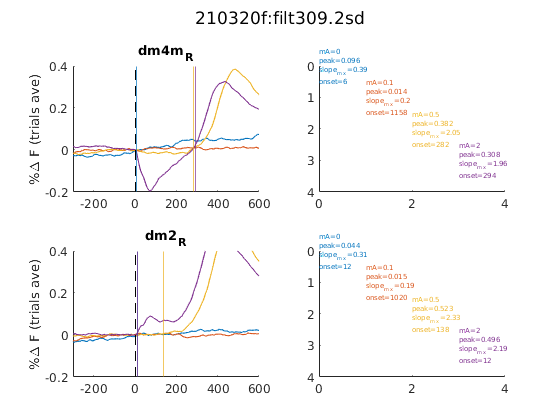


%% ----------------------------------------------------------------
%----------------------------------------------------------------
% COLLAPSED-MEASSURES
%----------------------------------------------------------------
%----------------------------------------------------------------

clearvars -except measure reject_on nfish cond_codes VSDI movies waves fcode ...
    window window_ave noise noise_ave rejectidx roiname1 roiname2 method lat_limit...
    wavesylim selroi setting

%@ SET : SELECT ONLY 2 ROIS (the code is hardwired to accept only 2 of them)

% SELECT CASES
sel_trials= [];

for condi = makeRow(cond_codes) %to make sure that only the conditions of interest are computed)
    condtrials = makeCol(find(VSDI.condition(:,1)==condi));
    sel_trials  = [sel_trials; condtrials];
end
sel_trials= sort(sel_trials);

if reject_on  %@ SET
    sel_trials = setdiff(sel_trials, rejectidx);
end



% ONSET OF  WAVES FROM CIRCULAR ROIS FROM ONE CONDITION AVERAGE

% build color matrix
colors = lines(length(cond_codes));

figure
ploti = 1;%counter

for nroi = makeRow(selroi)
    
    subplot(2,2,ploti) %waves from all conditions in the first column (loop through conditions)
    hold on;
    
    for codi = 1:length(cond_codes)
        code = cond_codes(codi);
        tricond = intersect(find(VSDI.condition(:,1) == code) , sel_trials);
        codemA(codi)= VSDI.condition(tricond(1),4); %mA corresponding to the code label (for the next subplot)
        roiwave = mean(waves(:,nroi,tricond),3) ;
        
        hold on;
        output = devo_peak2peak(roiwave, VSDI.timebase, window, noise, method, 0, 0);
        
        idx0= dsearchn(VSDI.timebase, 0);
        
        waveW = roiwave(idx0:output.peakidx(2));
        slopemean(nroi, codi) = mean(diff(waveW));
        
        slopemax(nroi,codi) = output.slopemax;
        peak(nroi,codi) = output.peakminusbasel;
        onset_ms(nroi,codi)= output.onsetnoise_ms;
        
        plot(VSDI.timebase,roiwave, 'color', colors(codi,:), 'linewidth', 0.8); hold on %  'linewidth', 1.8
        xline(onset_ms(nroi,codi), 'color', colors(codi,:),'linewidth', 0.8);
        xline(0,'--k');
        
        %         ylim([-0.2 .3])
        ylim(wavesylim.ave) %for high stimuli
        
        xlim([-300 600])
        ylabel('%\Delta F (trials ave)');
        
        title([ VSDI.roi.labels{nroi}])
        
        codelegend{codi} = num2str(code);
        
        clear output roiwave waveW slopeval
        
    end %codi
    
    %     legend (codelegend);
    hold off
    ploti = ploti+1;
    
    % initialize text coord
    %     ny = 10; % scaling factor (space between lines)
    %     nx = 10; %scaling factor (x space between blocks of text)
    %     x = 0;
    %     y = length(cond_codes)*ny*6; % 'nºconditions' * 'nº lines per condition' . the number of lines is doubled (x2) to leave a space between lines
    x=0; y=0;
    subplot(2,2,ploti) %waves from all conditions in the first column (loop through conditions)
    
    xlim([0 length(cond_codes)])
    ylim([0 length(cond_codes)])
    
    set(gca, 'ydir', 'reverse')
    for codi = 1:length(cond_codes)
        
        text(x, y, {['mA=', num2str(codemA(codi))],...
            ['peak=', num2str(round(peak(nroi,codi),3))],...
            ['slope_m_x=', num2str(round(slopemax(nroi,codi)*100,2))]...
            ['onset=',  num2str(onset_ms(nroi,codi))]...
            }, 'color', colors(codi,:), 'fontsize', 5)
        
        
        y = y +1;
        x = x +1;
    end
    
    ploti = ploti+1;
    
end %  roi


if reject_on
    sgtitle([num2str(VSDI.ref),'f:', fcode , '.', num2str(noise.SDfactor), 'sd' '(cl)'])
else
    sgtitle([num2str(VSDI.ref),'f:', fcode , '.', num2str(noise.SDfactor),'sd'])
end

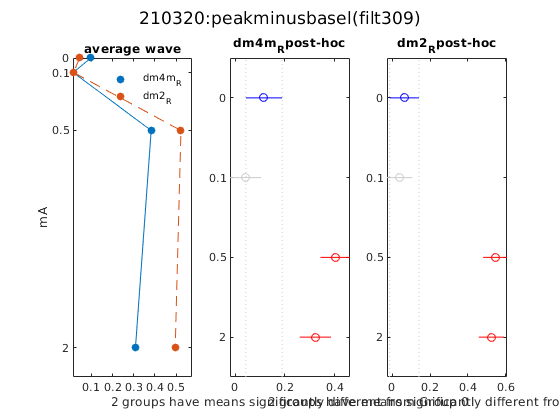

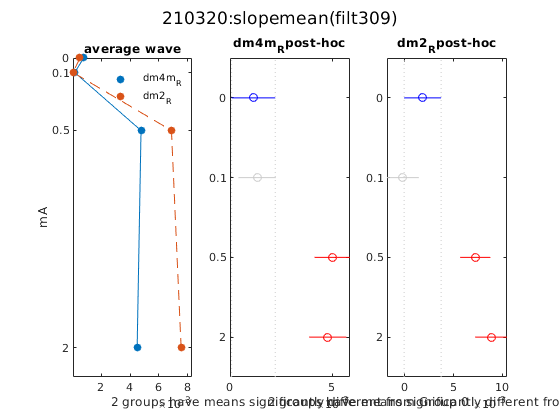

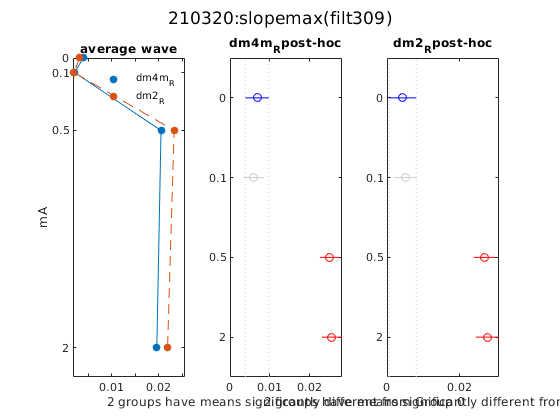

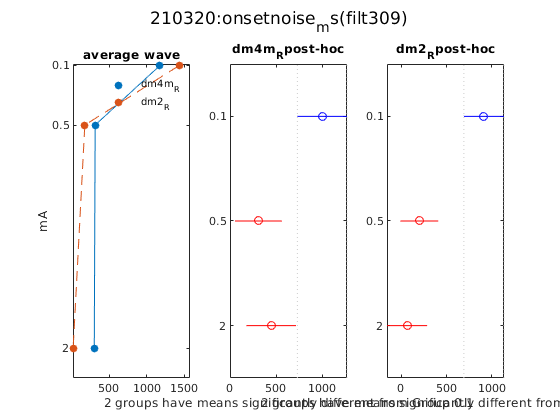



%% ----------------------------------------------------------------
%----------------------------------------------------------------
% COLLAPSED-RASTER_MULTIPLOT
%----------------------------------------------------------------
%----------------------------------------------------------------
clearvars -except measure reject_on nfish cond_codes VSDI movies waves fcode ...
    window window_ave noise noise_ave rejectidx roiname1 roiname2 method lat_limit...
    wavesylim selroi setting

% SELECT CASES
sel_trials= [];

for condi = cond_codes %to make sure that only the conditions of interest are computed)
    condtrials = makeCol(find(VSDI.condition(:,1)==condi));
    sel_trials  = [sel_trials; condtrials];
end
sel_trials= sort(sel_trials);

if reject_on  %@ SET
    sel_trials = setdiff(sel_trials, rejectidx);
end


% CALCULATE MEASURE FOR EACH TRIAL
for nroi = 1:length(VSDI.roi.labels)
    latency_out{nroi} = [];
    
    for triali = makeRow(sel_trials)
        %         disp(['trial:',num2str(triali)])
        wave = squeeze(waves(:, nroi,triali));
        output = devo_peak2peak(wave, VSDI.timebase, window,noise, method, 0, 0);
        
        measures.peak2peak(nroi,triali) = output.p2p_value;
        measures.peakminusbasel(nroi,triali) = output.peakminusbasel;
        %                         frames.peaklat(rowi,coli,triali) = output.peaklat_ms;
        %                         frames.p2plat(rowi,coli,triali) = output.p2plat_ms;
        %                         frames.onset30_latency_ms(rowi,coli,triali) = output.onset30_latency_ms;
        measures.onsetnoise_ms(nroi,triali) = output.onsetnoise_ms;
        
        measures.noisethresh(nroi,triali) = output.noisethresh;
        
        
        % store trials that will be rejected from latency means
        if measures.onsetnoise_ms(nroi,triali) > lat_limit
            latency_out{nroi} = [latency_out{nroi}  triali];
        end
        %         measures.noisethresh(nroi,triali) = output.noisethresh;
        
        measures.slopemax(nroi,triali) = output.slopemax;
        
        
        % get meanslope
        idx0= dsearchn(VSDI.timebase, 0);%get 0 index
        waveW = wave(idx0:output.peakidx(2));
        waveslope = diff(waveW);
        meanslope = mean(waveslope);
        
        measures.meanslope(nroi,triali) = meanslope;
        
        clear output wave waveW waveslope meanslope
        
    end %triali
end %nroi
%
% subplot(1,5,1)

% CALCULATE AVERAGE MEASURES
... the measure has to be computed for each condition label, while for the plots it's calculated trial-wise (and then the boxplot organizes it)
    
j=1; %
for code = makeRow(cond_codes)
    tricond = intersect(find(VSDI.condition(:,1) == code) , sel_trials);
    
    avewave = mean(waves(:,:,tricond),3) ;
    
    
    for nroi = 1:length(VSDI.roi.labels)
        roiwave = squeeze(avewave(:,nroi));
        output = devo_peak2peak(roiwave, VSDI.timebase, window_ave, noise_ave, method, 0, 0);
        
        idx0= dsearchn(VSDI.timebase, 0);%get 0 index
        waveW = roiwave(idx0:output.peakidx(2)); %calculate from 0 to peak
        slopeval = mean(diff(waveW));
        
        avemeasures.peakminusbasel(nroi,j) = output.peakminusbasel;
        avemeasures.onsetnoise_ms(nroi,j) = output.onsetnoise_ms;
        avemeasures.meanslope(nroi,j) = slopeval;
        avemeasures.slopemax(nroi,j) = output.slopemax;
        
        clear output roiwave waveW slopeval
    end %roi
    
    % get mA corresponding to each condition (for later plotting)
    mAcond(j)=VSDI.condition(tricond(1),4);
    j = j+1;
end

% MEASURE SELECTION

% close all


for resulti = 1:length(measure)
    
    result= measure{resulti};
    % BOXPLOT + STAT
    nroi1 = name2idx(roiname1, VSDI.roi.labels);
    nroi2 = name2idx(roiname2, VSDI.roi.labels);
    
    ... reinitialize variables
        measure1 = [];
    avemeasure1 = [];
    
    measure2 = [];
    avemeasure2 = [];
    
    extratitle = '';
    
    ccmap= lines(2);  %custom cmap
    
    % CONFIGURATION OF PARAMETERS THAT ARE SPECIFIC FOR EACH MEASURE
    switch result
        
        % ------------------------------------------------------------------------
        case 'peakminusbasel'
            
            measure1 = makeCol(squeeze(measures.peakminusbasel(nroi1,sel_trials)));
            avemeasure1 = squeeze(avemeasures.peakminusbasel(nroi1,:));
            
            measure2 = makeCol(squeeze(measures.peakminusbasel(nroi2,sel_trials)));
            avemeasure2 = squeeze(avemeasures.peakminusbasel(nroi2,:));
            
            % BUILD CONDITIONS (mA) MATRIX FOR ANOVA
            mA= [];
            mA = VSDI.condition(sel_trials,4); %mA
            
            local_mAcond = mAcond;
            
            % ------------------------------------------------------------------------
        case 'slopemean'
            
            measure1 = makeCol(squeeze(measures.meanslope(nroi1,sel_trials)));
            avemeasure1 = squeeze(avemeasures.meanslope(nroi1,:));
            
            measure2 = makeCol(squeeze(measures.meanslope(nroi2,sel_trials)));
            avemeasure2 = squeeze(avemeasures.meanslope(nroi2,:));
            
            
            % BUILD CONDITIONS (mA) MATRIX FOR ANOVA
            mA= [];
            mA = VSDI.condition(sel_trials,4); %mA
            
            local_mAcond= mAcond;
            
            % ------------------------------------------------------------------------
        case 'slopemax'
            
            measure1 = makeCol(squeeze(measures.slopemax(nroi1,sel_trials)));
            avemeasure1 = squeeze(avemeasures.slopemax(nroi1,:));
            
            measure2 = makeCol(squeeze(measures.slopemax(nroi2,sel_trials)));
            avemeasure2 = squeeze(avemeasures.slopemax(nroi2,:));
            
            
            % BUILD CONDITIONS (mA) MATRIX FOR ANOVA
            mA= [];
            mA = VSDI.condition(sel_trials,4); %mA
            
            local_mAcond= mAcond;
            
            % ------------------------------------------------------------------------
        case 'onsetnoise_ms' % leave the condition 0 out
            seltrials_onset = [];
            controltrials = find(VSDI.condition(:,1) == cond_codes(1)); %find control trials
            seltrials_onset = setdiff(sel_trials, controltrials); %leave out of the measure
            
            % BUILD CONDITIONS (mA) MATRIX FOR ANOVA
            
            mA= [];
            mA = VSDI.condition(seltrials_onset,4); %mA
            
            measure1 = makeCol(squeeze(measures.onsetnoise_ms(nroi1,seltrials_onset)));
            avemeasure1 = squeeze(avemeasures.onsetnoise_ms(nroi1,2:end)); %we skip the first condition
            
            measure2 = makeCol(squeeze(measures.onsetnoise_ms(nroi2,seltrials_onset)));
            avemeasure2 = squeeze(avemeasures.onsetnoise_ms(nroi2,2:end)); %we skip the first condition
            
            local_mAcond = mAcond(2:end);
            
    end
    
    %SCATTER PLOT (both regions together)
    figure
    subplot(1,3,1)
    p1= plot (avemeasure1, local_mAcond, 'color', ccmap(1,:)); hold on
    p2= plot (avemeasure2, local_mAcond, '--', 'color', ccmap(2,:)); hold on
    s1= scatter(avemeasure1, local_mAcond, [], ccmap(1,:), 'filled', 'displayname', roiname1); hold on
    s2= scatter(avemeasure2, local_mAcond, [], ccmap(2,:), 'filled', 'displayname', roiname2);
    
    ylabel('mA')
    ylim([local_mAcond(1)*0.9 local_mAcond(end)*1.1])
    xlim([min([avemeasure1 avemeasure2])*0.9 max([avemeasure1 avemeasure2])*1.1]) % xlimit according to the max min values
    yticks(mAcond)
    set(gca, 'ydir', 'reverse')
    title('average wave')
    lgnd = legend([s1 s2]);
    set(lgnd,'color','none', 'edgecolor', 'none');

    %MULTICOMPARE PLOTS (one for each region)
    
    [~, ~, stats1] = anova1(measure1,mA, 'off') ;
    
    h = subplot(1,3,2);
    [c, m , h, gnames] = multcompare_modif(stats1, 'CType', 'bonferroni');
    title([VSDI.roi.labels{nroi1} 'post-hoc'])
    
    [~, ~, stats2] = anova1(measure2,mA, 'off') ;
    
    h2 = subplot(1,3,3);
    [c, m , h2, gnames] = multcompare_modif(stats2, 'CType', 'bonferroni');
    title([VSDI.roi.labels{nroi2} 'post-hoc'])
    
    
    sgtitle([num2str(VSDI.ref), ':', result, '(', fcode, ')'])
    
end %result loop

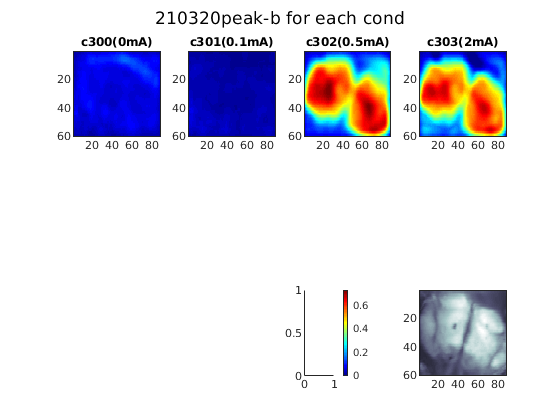

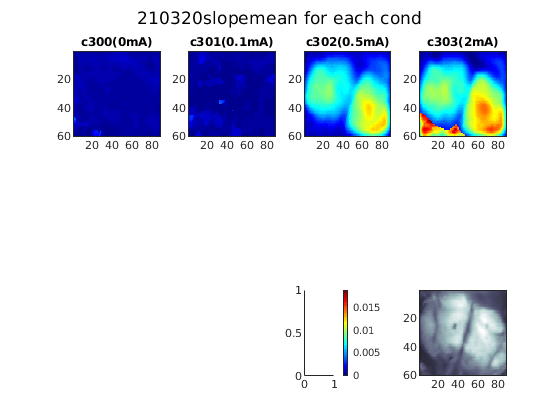

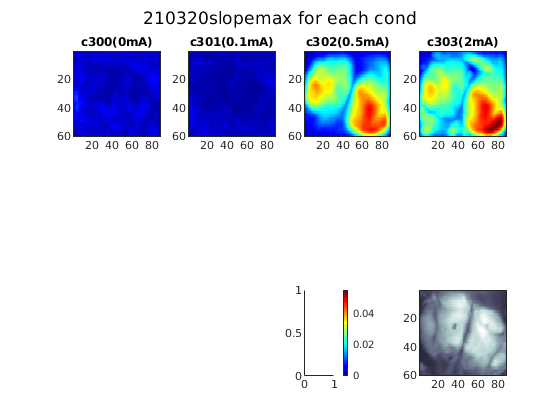

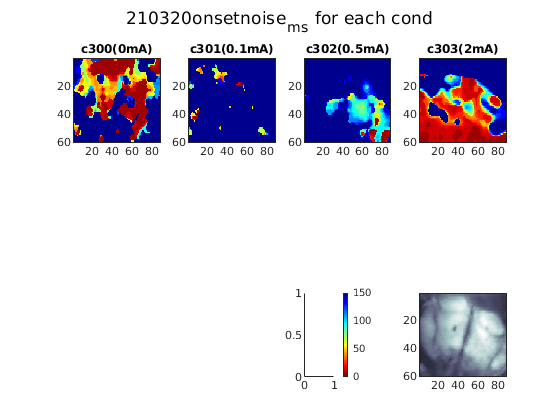


%% ----------------------------------------------------------------
%----------------------------------------------------------------
% MEASURES MAPS
%----------------------------------------------------------------
%----------------------------------------------------------------
clearvars -except measure reject_on nfish cond_codes VSDI movies waves fcode ...
    window window_ave noise noise_ave rejectidx roiname1 roiname2 method lat_limit...
    wavesylim selroi setting

% VISUALIZE MEASURES PIXEL-WISE.

%--------------------------------------
%1. APPLY FUNCTION TO THE AVERAGE-MOVIE FOR EACH CONDITION AND PLOT
%--------------------------------------
j = 1;

for condi = makeRow(cond_codes)
    sel_trials  = find(VSDI.condition(:,1)==condi);
    if reject_on  %@ SET
        sel_trials = setdiff(sel_trials, rejectidx);
    end
    
    avemovie = mean(movies(:,:,:,sel_trials),4);
    
    for rowi = 1:size(avemovie,1)
        for coli = 1:size(avemovie,2)
            wave = squeeze(avemovie(rowi, coli, :));
            output = devo_peak2peak(wave, VSDI.timebase, window,noise, method, 0, 0);
            
            frames.peak2peak(rowi,coli,j) = output.p2p_value;
            frames.peakminusbasel(rowi,coli,j) = output.peakminusbasel;
            frames.peaklat(rowi,coli,j) = output.peaklat_ms;
            frames.p2plat(rowi,coli,j) = output.p2plat_ms;
            frames.onset30_latency_ms(rowi,coli,j) = output.onset30_latency_ms;
            frames.onsetnoise_ms(rowi,coli,j) = output.onsetnoise_ms;
            frames.noisethresh(rowi,coli,j) = output.noisethresh;
            frames.slopemax(rowi,coli,j) = output.slopemax;
            
            peakidx.tmin(rowi,coli,j) = output.peakidx(1); %it'll be used for the calculation o
            peakidx.tmax(rowi,coli,j) = output.peakidx(2); %it'll be used for the calculation o
            
            clear output
        end %coli
    end %rowi
    
    j = j+1;
    %     display(condi)
    clear sel_trials
    
end %condi
%         blob()

%2. GET MAX-MIN AND PLOT THEM WITH THE SAME LIMITS
maxval.peak2peak= max(abs(frames.peak2peak(:)));
maxval.peakminusbasel= max(abs(frames.peakminusbasel(:)));
maxval.peaklat= max(abs(frames.peaklat(:)));
maxval.p2plat= max(abs(frames.p2plat(:)));
maxval.onset30_latency_ms= max(abs(frames.onset30_latency_ms(:)));
maxval.onsetnoise_ms= max(abs(frames.onsetnoise_ms(:)));
maxval.noisethresh= max(abs(frames.noisethresh(:)));
maxval.slopemax= max(abs(frames.slopemax(:)));

c_lim.peak2peak = [0 maxval.peak2peak(~isoutlier(maxval.peak2peak))];
c_lim.peakminusbasel = [0 maxval.peakminusbasel(~isoutlier(maxval.peakminusbasel))];
c_lim.peaklat = [0 maxval.peaklat(~isoutlier(maxval.peaklat))];
c_lim.p2plat = [0 maxval.p2plat(~isoutlier(maxval.p2plat))];
c_lim.onset30_latency_ms = [0 maxval.onset30_latency_ms];

c_lim.onsetnoise_ms = [0 150];

c_lim.noisethresh = [0 maxval.noisethresh(~isoutlier(maxval.noisethresh))];
c_lim.slopemax = [0 maxval.slopemax(~isoutlier(maxval.slopemax))]; %smaller color limits

BVmap = colormap_loadBV();


for resulti = 1:length(measure)
    
    result= measure{resulti};
    %----------------------------------------------------------------
    % CONFIGURATION OF PARAMETERS THAT ARE SPECIFIC FOR EACH MEASURE
    %----------------------------------------------------------------
    measureframe= [];
    localclim = [];
    
    switch result
        
        % ------------------------------------------------------------------------
        case 'peakminusbasel'
            
            measureframe = frames.peakminusbasel;
            
            localmap = jet;
            localclim = c_lim.peakminusbasel;
            
            
            localtitle = [num2str(VSDI.ref), 'peak-b for each cond'];
            localname = [num2str(VSDI.ref), '-peak-b(average mov)settings1'];
            
            
            % ------------------------------------------------------------------------
        case 'slopemax'
            
            measureframe = frames.slopemax;
            
            localmap = jet;
            localclim = c_lim.slopemax;
            
            localtitle = [num2str(VSDI.ref), 'slopemax for each cond'];
            localname = [num2str(VSDI.ref), '-slopemax(average mov)settings1'];
            
            
            % ------------------------------------------------------------------------
        case 'onsetnoise_ms'
            
            measureframe = frames.onsetnoise_ms;
            
            localmap = flipud(jet);
            localclim = c_lim.onsetnoise_ms;
            
            localtitle = [num2str(VSDI.ref), 'onsetnoise_m_s for each cond'];
            localname = [num2str(VSDI.ref), '-onsetnoise_ms(average mov)settings1'];
            
            % ------------------------------------------------------------------------
            
        case 'noisethresh'
            
            measureframe = frames.noisethresh;
            
            localmap = jet;
            localclim = c_lim.noisethresh;
            
            
            localtitle = [num2str(VSDI.ref), 'peak-b for each cond'];
            localname = [num2str(VSDI.ref), '-peak-b(average mov)settings1'];
            
            % ------------------------------------------------------------------------
        case 'slopemean' % in this case, the measure has to be computed
            
            % 1. CALCULATE MEASURE 'measureframe'
            j = 1;
            
            for condi = makeRow(cond_codes)
                sel_trials  = find(VSDI.condition(:,1)==condi);
                if reject_on  %@ SET
                    sel_trials = setdiff(sel_trials, rejectidx);
                end
                
                avemovie = mean(movies(:,:,:,sel_trials),4);
                
                for rowi = 1:size(avemovie,1)
                    for coli = 1:size(avemovie,2)
                        wave = squeeze(avemovie(rowi, coli, :));
                        output = devo_peak2peak(wave, VSDI.timebase, window, noise, method, 0, 0);
                        
                        idx0= dsearchn(VSDI.timebase, 0);%get 0 index
                        waveW = wave(idx0:output.peakidx(2));
                        slopemean = mean(diff(waveW));
                        
                        measureframe(rowi, coli, j) = slopemean;
                    end %coli
                end %rowi
                j = j+1;
                clear sel_trials
            end % condi
            
            %GET MAX AND PLOT THEM WITH THE SAME LIMITS
            localmax = max(abs(measureframe(:)));
            
            
            % 2. CONFIGURE THE OTHER PARAMETERS
            localmap = jet;
            localclim = [0 localmax];
            
            localtitle = [num2str(VSDI.ref), 'slopemean for each cond'];
            localname = [num2str(VSDI.ref), '-slopemean(average mov)settings1'];
            
    end % result case selection
    
    % %--------------------------------------
    % %  PLOT MEASURES
    % %--------------------------------------
    
    figure
    
    for ploti = 1:length(cond_codes)
        
        ax(ploti) = subplot(3,4,ploti);
        imagesc(measureframe(:,:,ploti))
        set (ax(ploti), 'clim', localclim)
        colormap(localmap)
        condidx = find(VSDI.condition(:,1) ==cond_codes(ploti)); % get idx from condition
        tempmA = VSDI.condition(condidx(1),4); %get mA from first trial that meet the condition
        title(['c',num2str(cond_codes(ploti)), '(', num2str(tempmA),'mA)'])
        
    end
    
    % plot colorbar
    ax(11) = subplot(3,4,11);
    colorbar
    set (ax(11), 'clim', localclim)
    colormap(localmap)
    
    %plot brain
    ax(12) = subplot(3,4,12);
    imagesc(VSDI.backgr(:,:,VSDI.nonanidx(1)));
    colormap(ax(12), bone)
    
    if  reject_on
        sgtitle([localtitle '(cl)'])
    else
        sgtitle(localtitle)
        
    end
    
    
end %result loop



%% ----------------------------------------------------------------
%----------------------------------------------------------------
% DISPLAY PARAMETERS
% ----------------------------------------------------------------
%----------------------------------------------------------------
clearvars -except measure reject_on nfish cond_codes VSDI movies waves fcode ...
    window window_ave noise noise_ave rejectidx roiname1 roiname2 method lat_limit...
    wavesylim selroi setting
display(reject_on)

reject_on = 0

display(fcode)

fcode = 'filt309'

display(method)

method = 'movsum'


display(window)

window = struct with fields:
         min: [-100 100]
         max: [0 600]
      movsum: 50
    baseline: [-300 0]
       slope: 50


display(noise)

noise = struct with fields:
    fr_abovenoise: 30
         SDfactor: 2


display(window_ave)

window_ave = struct with fields:
         min: [-100 100]
         max: [0 600]
      movsum: 50
    baseline: [-300 0]
       slope: 50


display(noise_ave)

noise_ave = struct with fields:
    fr_abovenoise: 30
         SDfactor: 4


if reject_on
    display(rejectidx)
    display(setting)
end

%% 
% namepdf = [num2str(VSDI.ref) '-block' num2str(cond_codes(1)) '.pdf'];
% % publish('source_code_mixed_pdf.mlx','pdf');
%
% mlxloc = strcat(pwd,'/source_code_mixed_pdf.mlx');
% fileout = strcat(pwd,namepdf);
% matlab.internal.liveeditor.openAndConvert(mlxloc,fileout);
blob()